# **Norma IEEE-754**

El año 1985, Institute for Electrical and Electronic Engineers (IEEE) va publicar el informe Binary Floating Point Arithmetic Standard 754 − 1985, en el que se especifican normas para representar numeros en punto flotante con precisión simple doble y formatos de precision extendidos. El año 2008 fue publicada el IEE Std 754-2008. 

La norma IEEE-754 define:

- Formatos aritméticos: conjuntos de datos de punto flotante binarios y decimales, que consisten en números finitos, includios los ceros con singo, y los números desnormalizados, infinitos y valores especiales "no numéricos" (Nan).

- Formatos de intercambio: codificaciones (cadenas de bits) que se pueden utilizar para intercambiar datos de punto flotante de forma eficiente y compacta.

- Reglas de redondeo: propiedades que deben satisfacer al redondear los numeros.

- Operaciones aritmeticas.

- Indicaciones de excepciones: overflow, underflow, divisiones por cero...

# **Formatos aritméticos**

## **Single and Double Precision:**

### **Single Precision**

la represenatción en punto flotante de simple precisión ocupa 1 word(32 digitos), asignando: 1 bit para el signo del numero real, 8 bits para el exponente y 23 bits para la mantisa. 

Un nombre real x en simple precisión se reprensenta de la siguiente manera:

              

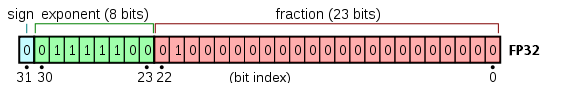

Donde **s** es el valor del signo. **c** es el valor del exponente (con signo).   el valor de la mantissa. 

Los valores de los exponentes con todo 0's o todo 1's, estan reservados. 

### **Denormal number (Single Precision)**

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los numeros normalizados, es decir, s es el valor del signo y    el valor de la mantissa. El valor del exponente no se utiliza.

### **Double Precision**

la representación en punto flotante con doble precision ocupa 2 words(64 digitos), asignando: 1 bit para el signo del numero real, 11 bits para el exponente y 52 bits para la mantisa.

Un nombre real x en simple precisión se reprensenta de la siguiente manera:

            

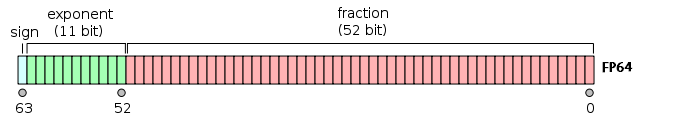

Donde **s** es el valor del del signe. **c** es el valor del exponente (con signo).  el valor de la mantisa.

Los valores de los exponentes con todo 0's o todo 1's, estan reservados. 

### **Denormal number (Double Precision)**

Si el exponente es 0 y la mantisa diferente de 0. 

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los numeros normalizados, es decir, s es el valor del signo y    el valor de la mantissa. El valor del exponente no se utiliza.

### Inf

Si el exponente es todos 1 y la mantisa es 0 representa a los numeros infinitos. En caso de que el signo sea 0 respresenta el +infinito.En caso de que el signo sea 1 representa -infinito.

### **Nan(Not-A-Number)**

Si el exponente es todos 1 y la mantisa es diferente de 0 representa Nan(Not-A-Number).  Esto se utiliza para expresar un resultado imposible de calcular (raíces negativas, division por cero)...

### **Zero**

Si el exponente es todos 0 y la mantisa 0 representa al 0. En caso de que el signo sea 0 representa el +0. En casi de que el signo sea 1 representa -0.

Fenomenos producidos por la artimetica

# **Fenomenos producidos por la aritmetica **

**roundoff error**

**underflow**

**overflow**

# **Resumen Norma IEEE-754**

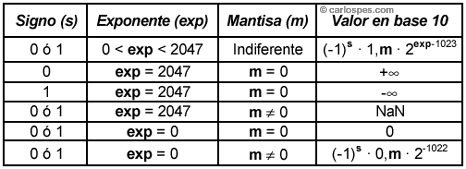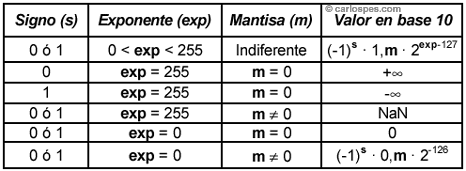

**Biografia:**

[https://es.wikipedia.org/wiki/IEEE_coma_flotante](https://es.wikipedia.org/wiki/IEEE_coma_flotante)

[https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/](https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/)

[https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/](https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/)

# Exercici2

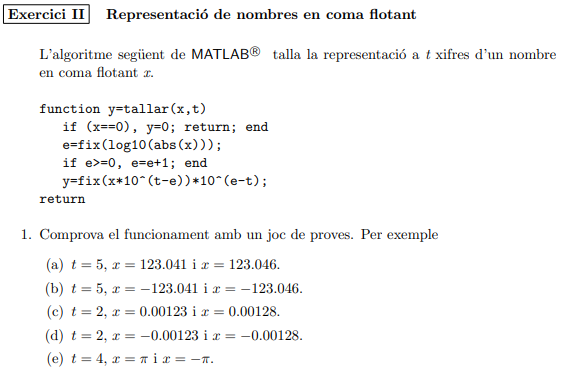

**a)**

format compact
format long
t = 5;
x = 123.051;
ya = tallar(x,t)

ya =      1.230500000000000e+02

x = 123.046;
ya = tallar(x,t)

ya =      1.230400000000000e+02

**b)**

t = 5;
x = -123.041;
yb = tallar(x,t)

yb =     -1.230400000000000e+02

x = -123.046;
yb = tallar(x,t)

yb =     -1.230400000000000e+02

**c)**

t = 2;
x = 0.00123;
yc = tallar(x,t)

yc =    0.001200000000000

x = 0.00128;
yc = tallar(x,t)

yc =    0.001200000000000

**d)**

t = 2;
x = -0.00123;
yd = tallar(x,t)

yd =   -0.001200000000000

x = -0.00128;
yd = tallar(x,t)

yd =   -0.001200000000000

**e)**

t = 4;
x = pi;
ye = tallar(x,t)

ye =    3.141000000000000

x = -pi;
ye = tallar(x,t)

ye =   -3.141000000000000

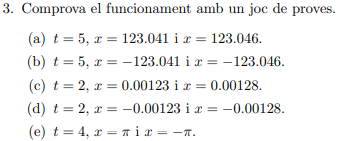

t = 5;
x = 123.051;
ya = redondear(x,t)

ya =      1.230500000000000e+02

x = 123.046;
ya = redondear(x,t)

ya =      1.230500000000000e+02

**b)**

t = 5;
x = -123.041;
yb = redondear(x,t)

yb =     -1.230400000000000e+02

x = -123.046;
yb = redondear(x,t)

yb =     -1.230500000000000e+02

**c)**

t = 2;
x = 0.00123;
yc = redondear(x,t)

yc =    0.001200000000000

x = 0.00128;
yc = redondear(x,t)

yc =    0.001300000000000

**d)**

t = 2;
x = -0.00123;
yd = redondear(x,t)

yd =   -0.001200000000000

x = -0.00128;
yd = redondear(x,t)

yd =   -0.001300000000000

**e)**

t = 4;
x = pi;
ye = redondear(x,t)

ye =    3.142000000000000

x = -pi;
ye = redondear(x,t)

ye =   -3.142000000000000

# Exercici 3

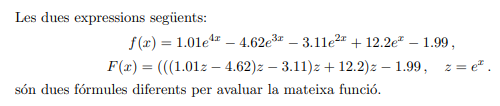

e = exp(1);
f_original = @(x) 1.01*e^(4*x)-4.62*e^(3*x)-3.11*e^(2*x)+12.2*e^x-1.99

f_original = function_handle with value:
    @(x)1.01*e^(4*x)-4.62*e^(3*x)-3.11*e^(2*x)+12.2*e^x-1.99



f = @(x,t)redondear(1.01*redondear(e^(4*x),t),t)-redondear(4.62*redondear(e^(3*x),t),t)-redondear(3.11*redondear(e^(2*x),t),t)+redondear(12.2*(e^x),t)-1.99;

F = @(x,t)redondear(redondear(redondear(redondear(redondear((redondear(redondear(redondear(1.01*redondear(e^x,t),t)-4.62,t)*redondear(e^x,t),t)-3.11),t)*redondear(e^x,t),t)+12.2,t)*redondear(e^x,t),t)-1.99,t)

F = function_handle with value:
    @(x,t)redondear(redondear(redondear(redondear(redondear((redondear(redondear(redondear(1.01*redondear(e^x,t),t)-4.62,t)*redondear(e^x,t),t)-3.11),t)*redondear(e^x,t),t)+12.2,t)*redondear(e^x,t),t)-1.99,t)


f1 = f(1.53,3)

f1 = -6.8900

F1 = F(1.53,3)

F1 = -7.0700

f1_original = f_original(1.53)

f1_original = -7.6079

f2 = f(0.925,4)

f2 = -24.2500

F2 = F(0.925,4)

F2 = -24.2600

f2_original = f_original(0.925)

f2_original = -24.2489

errorf1 = abs(f1_original-f1)/abs(f1_original)*100

errorf1 = 9.4359

errorF1 = abs(f1_original-F1)/abs(f1_original)*100

errorF1 = 7.0699


errorf2 = abs(f2_original-f2)/abs(f2_original)*100

errorf2 = 0.0044

errorF2 = abs(f2_original-F2)/abs(f2_original)*100

errorF2 = 0.0457

**Como podemos observar  a la hora de realizar la aritmetica con redondeo nos da diferentes valores aunque las funciones sean las mismas. El motivo principal es porque la funcion F(X) solo requiere hacer n multiplicaciones sobre el factor e^(x). En contra posicion la funcion f(x) realiza n multiplicaciones tambien pero sobre factores como e^(4x),e^(3x),etc.**

**Provocando la minimizacion del  numero de multiplicaciones que es lo mas deseable ya que son inestables.**

**En definitiva F(x) es lo que se obtiene tras realizar el algoritmo de Horner sobre f(x).**

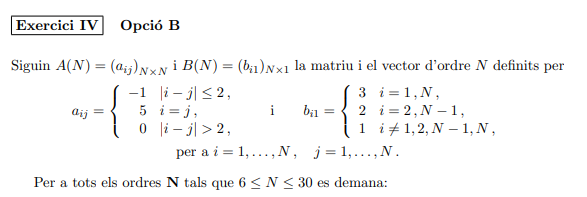

[A, b] = data_exercise_4(20)

A =      5    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1    -1     5    -1    -1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    

b =      3
     2
     1
     1
     1
     1
     1
     1
     1
     1


x= A\b

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


determinant = det(A)

determinant = 9.2165e+12

nombre_de_condicio = cond(A)

nombre_de_condicio = 6.4929

nombre_de_condicio = norm(A)* norm(A^-1)

nombre_de_condicio = 6.4929

isequal(A,A')

ans = logical
   1


# Eliminació Gaussiana (Metode directe)

[L,U,P] = lu(A);
% 1) Ly = Pb
y = forward(L, P*(b));
% 2) Ux = y
x = backsubs(U,y)

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


% comprobar residuo
r = b - A*x

r = 	1.0e+-15 *

         0
   -0.8882
         0
   -0.2220
   -0.2220
    0.4441
    0.6661
    0.8882
   -0.4441
         0


**El beneficio que obtenemos de usar la eliminacion Gaussiana para la matriz en este caso en concreto es que en el paso k del metodo Gaussiana solo tenemos que restar el pivot k a 2 filas que son la fila k+1 y la fila k+2.Eso es porque ya se encuentran todas las demás  a 0. **

**Al ser una matriz tridiagonal también se podria resolver con una variante de la eliminacion Gaussian llamado algoritmo de Thomas.**

# Factorització QR (Metode directe)

%Q*R = A
[Q,R] = qr(A);
%1) Rx = Q'b
x = backsubs(R,Q'*b)

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


%comprobar que el residuo es 0
r = b -A*x

r = 	1.0e+-14 *

    0.1776
   -0.1776
    0.0222
         0
    0.0777
    0.1221
    0.0111
         0
    0.4219
   -0.0444


i = 6

i = 6

I = 30

I = 30

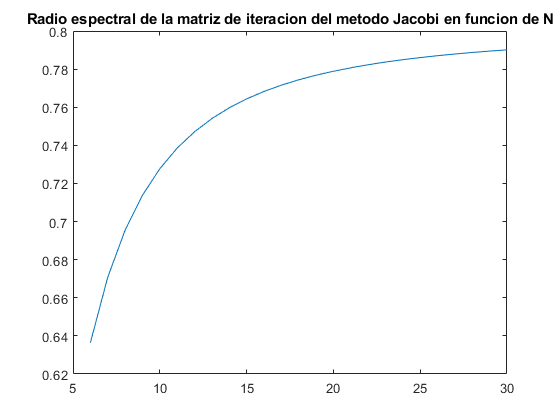

for N = i:I
    [A, b] = data_exercise_4(N);
    D=diag(diag(A));
    d=diag(1 ./diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    Bj=-d*(A-D);
    d=inv(L+D);
    Bgs=-d*U;
    rhoJ(N-5)=max(abs(eig(Bj)));
    rhoGs(N-5)=max(abs(eig(Bgs)));
    simetrica(N-5) = isequal(A,A');
    try chol(A);     
        definida_positiva(N-5) = true;
    catch ME
        definida_positiva(N-5) = false;
    end
end
plot(6:30, rhoJ), title('Radio espectral de la matriz de iteracion del metodo Jacobi en funcion de N')

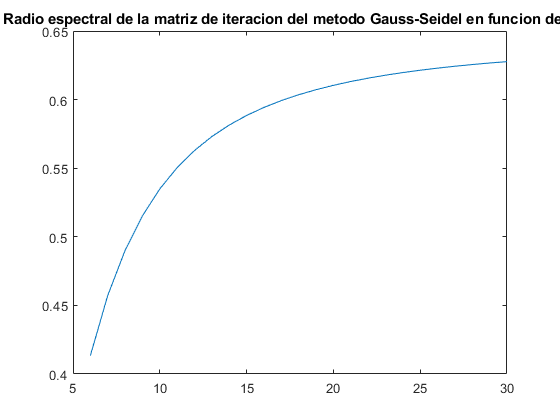

plot(6:30, rhoGs), title('Radio espectral de la matriz de iteracion del metodo Gauss-Seidel en funcion de N')

**Comprovació simetrica**

isequal(simetrica,logical(ones(1,(I-i)+1)))

ans = logical
   1


**Comprovació definida positiva**

isequal(definida_positiva,logical(ones(1,(I-i)+1)))

ans = logical
   1


**Como podemos observar también cumple la condición de matrices donde Di son submatrices diagonales, Ui, Li son submatrices qualesquera que satisfacen las condiciones pertinente para aplicar el teorema Ostrowski y Reich. Como podemos observar en la grafica, tambien cumple la condicion de que el radio espectral de la matriz BGS es igual a Bj^2.**

**Lo que significa que podemos obtener el coeficiente de relajación optimo a partir de la formula correspondiente.**

# Teorema Ostrowski y Reich

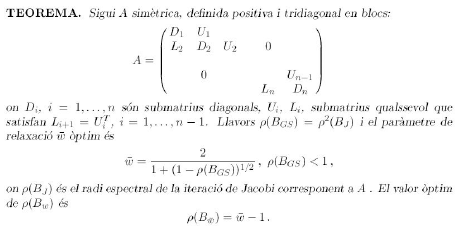

function y=tallar(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = fix(x*10^(t-e))*10^(e-t);
    return
end
function y=redondear(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = round(x*10^(t-e))*10^(e-t);
    return
end

function [A, b] = data_exercise_4(N)
    A = zeros(N);
    for i = 1:N
        for j = 1:N
            if abs(i-j) <= 2 && i ~= j
                A(i,j) = -1;
            elseif  i == j
                A(i,j) = 5;
            else
                A(i,j) = 0;
            end
        end
    end
    b = ones(1,N)*3;
    b(2) = 2;
    b(N-1) = 2;
    b(3:N-2) = 1;
    b = b';
end

function x = forward(L,x)
% FORWARD. Forward elimination.
% For lower triangular L, x = forward(L,b) solves L*x = b.
[n,n] = size(L);
x(1) = x(1)/L(1,1);
for k = 2:n
   j = 1:k-1;
   x(k) = (x(k) - L(k,j)*x(j))/L(k,k);
end
end

% ------------------------------

function x = backsubs(U,x)
% BACKSUBS.  Back substitution.
% For upper triangular U, x = backsubs(U,b) solves U*x = b.
[n,n] = size(U);
x(n) = x(n)/U(n,n);
for k = n-1:-1:1
   j = k+1:n;
   x(k) = (x(k) - U(k,j)*x(j))/U(k,k);
end
end
